# Figure 1: 1D map can reproduce the same results as biophysical mode

### Fig B and Fig D: illustration of BTSP, flat firing rate and bumpy firing rate

We generate the weight matrix to visualize the flat and bumpy firing rate before and after the learning.

The weights for the biphysical model and 1D map simulation are done in the script ***9_generate_network_weight.mlx ***section **Figure 1B&D**.

For more detail, please move to there.

To make the figure in 1A, the setup 

Export figure setup: 10.5 - 7

Inkscape setup: 

cd G:\Files\Matlab\Neuroscience\Simulation\paper_20220914
clear; clc
load Files/weight_matrix/Fig1/Simulations.mat

ind_pos = inductions(inductions(:, 1) == 1, 2);


init_weight = synaptic_weight_map(1, :);
final_weight = synaptic_weight_map(2, :);

figure
plot(ca3_peak_locations_map, init_weight, "LineWidth", 4.5, "Color", "[0, 0.4, 1]")
box off
axis tight
ylim([-0.1, 0.75])
xlim([0, L])
yticks([0])
xline(ind_pos, "k--", "LineWidth", 4.5)
xticks([0, ind_pos, L])
xticklabels(["0",  " ", "L"])
fig_config(80)

plot(ca3_peak_locations_map, final_weight, "LineWidth", 4.5, "Color", "[0, 0.4, 1]")
box off
axis tight
ylim([-0.1, 0.75])
xlim([0, L])
yticks([0])
xline(ind_pos, "k--", "LineWidth", 4.5)
xticks([0, ind_pos, L])
xticklabels(["0",  " ", "L"])
fig_config(80)

### figure E: Obtain the $f_P$ and $f_D$ based on the skew-t probability density

Wrapping the skew-t PDF to obtain the depression process $f_D$:

- First of all, We define the skew-t PDF in the time domain.

- Since the velocity is constant, we could relate the time domain and space domain through the linear relationship, X = time * velocity + plateau onset position -> we obtain the definition of skew-t PDF on the space domain aligned to the start point of the track.

- Next, we turn the space domain to the periodic phase domain as $(X \mbox{ Mod } L)/L * 2\pi -> \theta$

- For each $\theta$, we sum the PDF to obtain the wrapped skew-t PDF as $f_D$.

Each step corresponding to each plot, respectively.

Export figure setup: 10.5 - 7

inkscape: 51.15 - 38.5

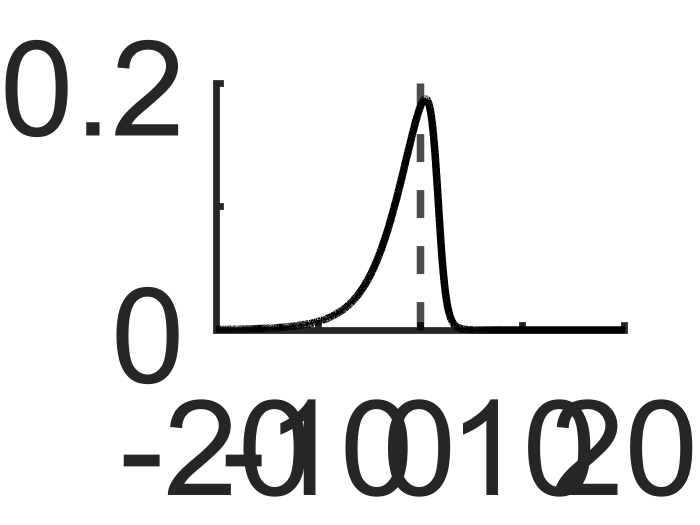

% plasticity in time domain
param = [5, 1.725, 3.6, -5.3];   % parameter of the skew-t density 
% degree of freedom; location; scale; skewness
nu = param(1);
mu = param(2);
sigma = param(3);
skew = param(4);
skew_t_density = @(x) 2/sigma .* tpdf((x  - mu)/sigma, nu) .* ...
            tcdf(skew * (x- mu)/sigma .* ...
            sqrt( (nu+1)./(nu+ (x- mu).^2/sigma^2) ), nu + 1);   % skew t density

v = 25; % cm/s  velocity of the animal
L = 187; % cm   length of treadmill

t = -20:0.01:20; % times domain
figure
f_skew_t= skew_t_density(t);
plot(t, f_skew_t, "-k", "LineWidth", 4.5); % skew-t density defined in time domain
xline(0, "--k", "LineWidth", 4.5)          % x label Time from PP (s)
box off
xticks([-4:2:4]*5)
yticks([0:0.1:0.2])
yticklabels([0, " ", 0.2])
fig_config(80)

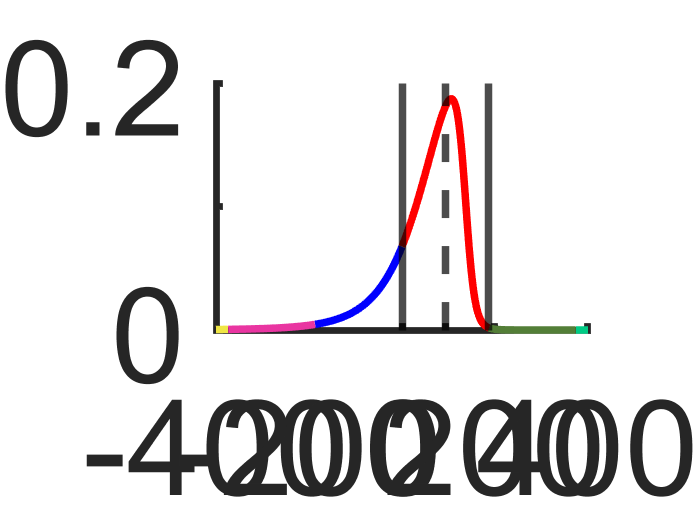


% plasciticy in x domain
figure
plateau = L/2;           % Supposing the plateau onse is occured when animal passing L/2 of the track
space_aling_track = t*v + plateau;     % since the velocity is constant, we can transform the time domain to space domain aligning with track 
%{
plot(space_aling_track, f_skew_t, "-k", "LineWidth", 4.5) 
xline(plateau , "--k", "LineWidth", 4.5)
xline(0, "-k", "LineWidth", 4.5)
xline(L, "-k", "LineWidth", 4.5)
hold on
desire_dots = [-1:0]*L-plateau;
f_skew_dots = skew_t_density(desire_dots/v);
desire_dots = desire_dots + plateau;
plot(desire_dots(1), f_skew_dots(1), "or", "MarkerSize", 15, "LineWidth", 4);
plot(desire_dots(2), f_skew_dots(2), "ob", "MarkerSize", 15, "LineWidth", 4);
hold off
box off
axis tight
ylim([0, 0.2])
yticks([0:0.1:0.2])
yticklabels([0, " ", 0.2])
xticks([[-4:2:0]*100, plateau, [2:2:4]*100])
xticklabels([[-4:2:0]*100, " ", [2:2:4]*100])
xlim([-400, 400])
fig_config(80)
%}

part_e = fix(space_aling_track / L);
part = space_aling_track/L;
part_res = mod(space_aling_track, L);
position = part_res;
index = unique(part_e);

cols = [239 230 69; 
    233 53 161; 
    0 0 255; 
    255 0 0; 
    83 126 55; 
    0 203 133]/255;

hold on
for i = 1:length(index)
    lap_i = index(i);
    condition = part < lap_i & part > lap_i - 1;
    space_i = space_aling_track(condition);
    f_skew_t_i = f_skew_t(condition);
    plot(space_i, f_skew_t_i, "color", cols(i, :), "LineWidth", 4.5)
end
axis tight
ylim([0, 0.2])
yticks([0:0.1:0.2])
yticklabels([0, " ", 0.2])
xticks([[-4:2:0]*100, plateau, [2:2:4]*100])
xticklabels([[-4:2:0]*100, " ", [2:2:4]*100])
xlim([-400, 400])
fig_config(80)
xline(plateau , "--k", "LineWidth", 4.5)
xline(0, "-k", "LineWidth", 4.5)
xline(L, "-k", "LineWidth", 4.5)

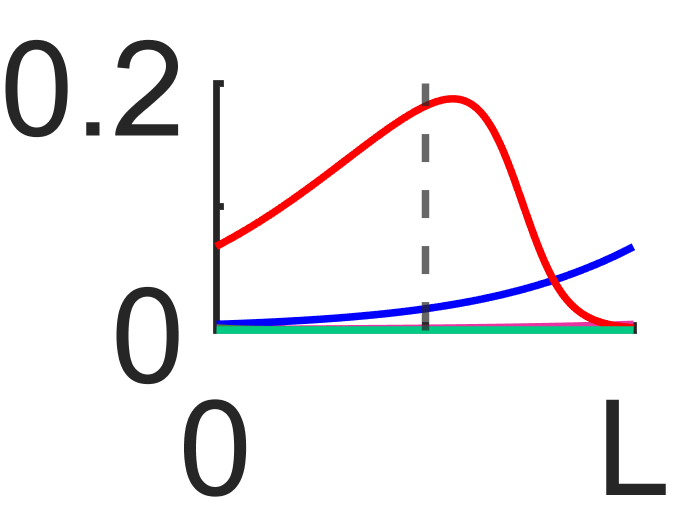


figure
hold on
for i = 1:length(index)
    lap_i = index(i);
    condition = part < lap_i & part > lap_i - 1;
    part_res_i = part_res(condition);
    f_skew_t_i = f_skew_t(condition);
    plot(part_res_i, f_skew_t_i, "color", cols(i, :), "LineWidth", 4.5)
end
hold off
xlim([0, L])
xline(plateau, "--", "LineWidth", 4.5)
xticks([0, plateau, L])
xticklabels([0, " ", "L"])
yticks([0:0.1:0.2])
yticklabels([0, " ", 0.2])
fig_config(80)

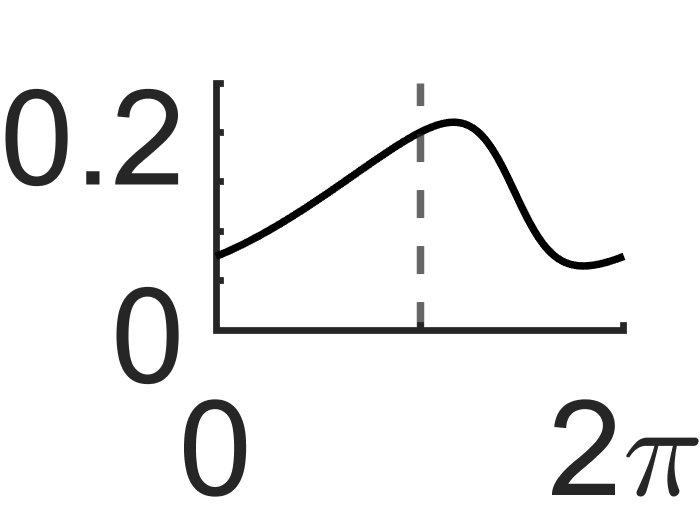


figure
phase = part_res /L *2 * pi;
ca3_location = 0:0.1:L;
relative_plateau_onset = (ca3_location - plateau) / v;
phase = ca3_location / L * 2 * pi;
f = plasticity(nu, mu, sigma, skew, v, L);
process = f(relative_plateau_onset);
plot(phase, process, "-k", "LineWidth", 4.5)
axis tight
xticks([0, pi, 2*pi])
xticklabels([0, " ", "2\pi"])
xline(plateau/L * 2* pi, "--", "LineWidth", 4.5)
ylim([0, 0.25])
yticks([0:0.05:0.25])
yticklabels([0, "", "", "", 0.2, ""])
box off
fig_config(80)

### Fig F: Comparison of underlying potentiation and depression process

Take advantage of the simulation done in the panel B, we can compute the plasticity rule in both model to see the 1D map can capture the bio model.

Export figure setup: 10.5 - 7

inkscape: 57.200 - 36.400

clear; clc
load Files/weight_matrix/Fig1/Simulations.mat
i = 1;
pot_r = list_pot(i, :);
pot_m = list_pot_map(i, :);
dep_r = list_dep(i, :);
dep_m = list_dep_map(i, :);

ind_pos = inductions(inductions(:, 1) == 1, 2);
phase_map = ca3_peak_locations_map / L * 2*pi;
phase = ca3_peak_locations /  L * 2*pi;
phase_ind = ind_pos /  L * 2*pi;  

plot(phase, pot_r, ".k" , "MarkerSize", 30)
hold on
plot(phase_map, pot_m, "-r", "LineWidth", 4.5)
xline(phase_ind, "--k", "LineWidth", 4.5)
legend({"Biophysical", "P\cdotf_P"}, 'location', 'northeast')
legend boxoff
hold off
box off
ylim([0, 0.8])
yticks([0, 0.2, 0.4, 0.6, 0.8])
yticklabels([0, "", "", "", 0.8])
xlim([0, 2*pi])
xticks([0, pi, 2*pi])
xticklabels([0, " ", "2\pi"])
fig_config(80)

plot(phase, dep_r, ".k" , "MarkerSize", 30)
hold on
plot(phase_map, dep_m, "-b", "LineWidth", 4.5)
xline(phase_ind, "--k", "LineWidth", 4.5)
legend({"Biophysical", "P\cdotf_D"}, 'location', 'northeast')
legend boxoff
hold off
box off
ylim([0, 0.8])
yticks([0, 0.2, 0.4, 0.6, 0.8])
yticklabels([0, "", "", "", 0.8])
xlim([0, 2*pi])
xticks([0, pi, 2*pi])
xticklabels([0, " ", "2\pi"])
fig_config(80)

### Fig G: Comparison of plasticity rule in both model

In the Milstein et.al. 2021, they showed that the plasticity map generated by the biophysical model was similar to the data.

Here, we show the 1D map can reproduce the similar heatmap of weight change using different parameter setting.

The weights for the biphysical model and 1D map simulation are done in the script ***9_generate_network_weight.mlx ***section **Figure 1G**.

For more detail, please move to there.

Export figure setup: 10.5 - 7

ink: 52.5 - 35

clear; clc
load Files/weight_matrix/Fig1/Simulations_heatmap.mat
i = 1;
pot_r = list_pot(i, :);
pot_m = list_pot_map(i, :);
dep_r = list_dep(i, :);
dep_m = list_dep_map(i, :);

ind_pos = inductions(inductions(:, 1) == 1, 2);

init_weights = 0:0.01:1;
init_weights = init_weights';
romani_plasticity = pot_r .* (1 - init_weights) - dep_r .* init_weights;
map_plasticity = pot_m .* (1-init_weights) - dep_m .* init_weights;

figure
time_axis = (ca3_peak_locations_map - ind_pos) / L * 2*pi;
imagesc(time_axis, init_weights, romani_plasticity)
xlim([-pi, pi])
xticks([-pi, 0, pi])
xticklabels(["-\pi", 0, "\pi"])
yticks(0.2 * (0:5))
yticklabels([0, "", "", "", "", 1])
set(gca,'YDir','normal')
colorbar
colormap(jet)
c = colorbar;
c.Ticks = [-0.5, 0, 0.5];
c.FontSize = 70;
fig_config(80)


figure
times_map = (ca3_peak_locations_map - ind_pos) / L * 2*pi;
imagesc(times_map, init_weights, map_plasticity)
xlim([-pi, pi])
xticks([-pi, 0, pi])
xticklabels(["-\pi", 0, "\pi"])
yticks(0.2 * (0:5))
yticklabels([0, "", "", "", "", 1])
set(gca,'YDir','normal')
colorbar
colormap(jet)
c = colorbar;
c.Ticks = [-0.5, 0, 0.5];
c.FontSize = 70;
fig_config(80)

### Fig H: Comparison of synaptic weight for 2 different consecutive inductions

Finally, we illustate the synaptic weight after different plateu induction positon to see the equivalence of both model.

Inductions: first when animal crosses the position 30 cm, and second, 90.

Export figure setup: 10.5 - 7  to PNG

clear; clc;
cd G:\Files\Matlab\Neuroscience\Simulation\paper_20220914
load Files/weight_matrix/Fig1/Simulations_two_inductions.mat

figure
% first induction
lap_1 = inductions(1, 1);
ind_1 = inductions(1, 2);
weight_R = synaptic_weight(lap_1 + 1, :);
weight_M = synaptic_weight_map(lap_1 + 1, :);
plot(ca3_peak_locations, weight_R, ".k", "MarkerSize", 30)
hold on
box off
plot(ca3_peak_locations_map, weight_M, "-k", "LineWidth", 4.5)
hold off
xline(ind_1, "--", "LineWidth", 4.5)
xlim([0, L])
legend boxoff
xticks([0, 187/2, 187])
xticklabels(["0", "", "2\pi"])
ylim([0, 1])
yticks([0, 0.5, 1])
yticklabels([0, "", 1])
legend({"Biophysical", "Map"})
fig_config(80)

% second
lap_2 = inductions(2, 1);
ind_2 = inductions(2, 2);
weight_R = synaptic_weight(lap_2 + 1, :);
weight_M = synaptic_weight_map(lap_2 + 1, :);

plot(ca3_peak_locations, weight_R, ".k", "MarkerSize", 30)
hold on
box off
plot(ca3_peak_locations_map, weight_M, "-k", "LineWidth", 4.5)
xline(ind_2, "--", "LineWidth", 4.5)
hold off
xlim([0, L])
xticks([0, 187/2, 187])
xticklabels(["0", "", "2\pi"])
ylim([0, 1])
yticks([0, 0.5, 1])
yticklabels([0, "", 1])
fig_config(80)

## Auxiliar functions

function f = plasticity(nu, mu, sigma, skew, velocity, L)
        
        f = @(x) 0;
        k_max = 5;
        for k = -1*k_max  : k_max
            f = @(x) f(x) + 2/sigma .* tpdf((x + L / velocity *k - mu)/sigma, nu) .* ...
                tcdf(skew * (x + L / velocity *k - mu)/sigma .* ...
                sqrt( (nu+1)./(nu+ (x + L / velocity *k - mu).^2/sigma^2) ), nu + 1);
        end
end
